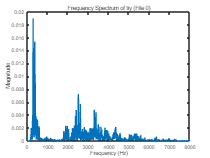

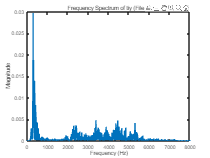

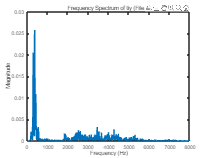

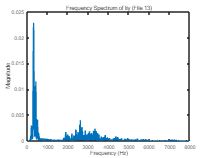

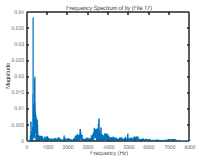

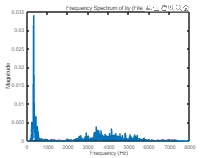

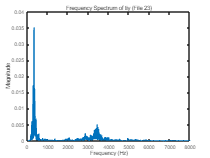

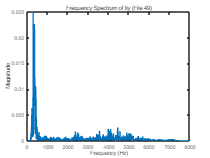

clear; close all; clc;

base_path = 'D:\W00Y0NG\PRGM2\MATLAB\2023mathFFT\MM18\kinect_data\';
phoneme_files = {
    'tiy', [0, 3, 5, 13, 17, 18, 23, 49, 58, 69, 76, 78],  
    'iy',  [1, 32, 40, 42, 44, 53, 57, 63, 67, 70, 74, 79],
    'piy', [2, 12, 19, 20, 25, 30, 33, 38, 39, 41, 68, 83],
    'm',   [4, 6, 10, 21, 24, 27, 28, 35, 36, 43, 54, 64],
    'n',   [7, 11, 15, 16, 22, 29, 37, 47, 55, 65, 72, 82],
    'diy', [8, 9, 14, 46, 48, 50, 52, 59, 62, 71, 73, 77],
    'uw',  [26, 31, 34, 45, 51, 56, 60, 61, 66, 75, 80, 81]
};

for i = 1:size(phoneme_files, 1)
    phoneme = phoneme_files{i, 1};
    fileIndices = phoneme_files{i, 2};

    for j = 1:length(fileIndices)
        filename = fullfile(base_path, sprintf('%d.wav', fileIndices(j)));
        [y, Fs] = audioread(filename);
        
        % 신호 강화
        y = y / max(abs(y));

        Y = fft(y);
        P2 = abs(Y/length(y));
        P1 = P2(1:length(y)/2+1);
        P1(2:end-1) = 2*P1(2:end-1);
        
        f = Fs*(0:(length(y)/2))/length(y);
        
        % FFT 결과 시각화
        figure;
        plot(f, P1);
        title(['Frequency Spectrum of ', phoneme, sprintf(' (File %d)', fileIndices(j))]);
        xlabel('Frequency (Hz)');
        ylabel('Magnitude');
        
        % FFT 결과를 파일로 저장
        saveFileName = sprintf('FFT_result/FFT_%s_%d.mat', phoneme, fileIndices(j));
        save(fullfile(saveFileName), 'f', 'P1');
    end
end